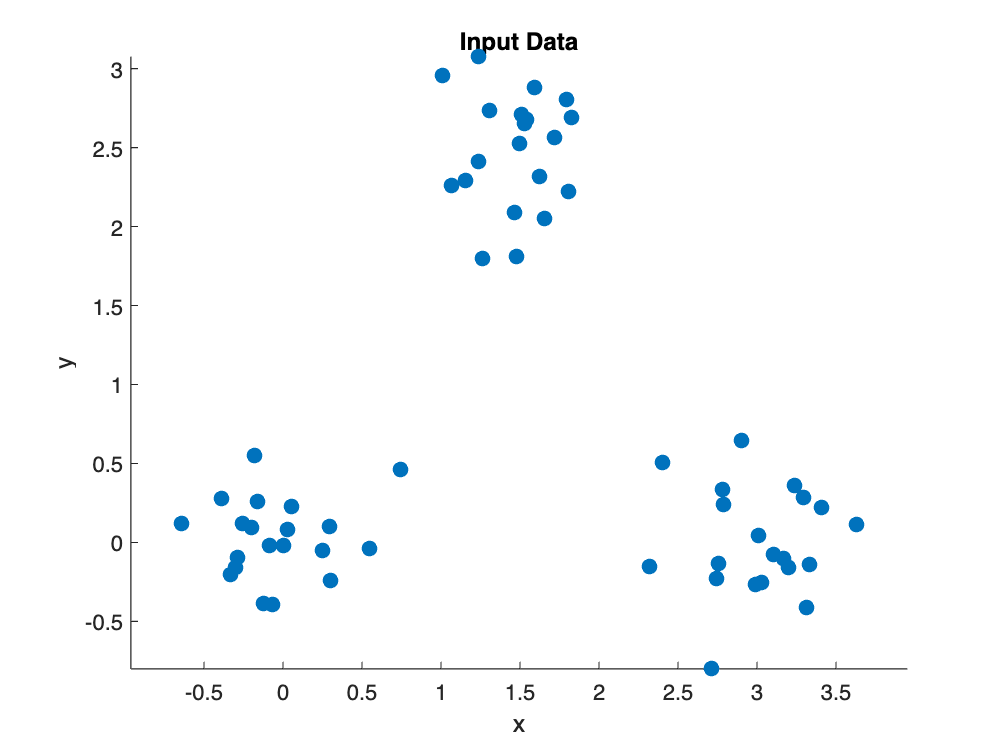

% Test script for kmeans_sdp.m

% Parameters
rng(42);                     % for reproducibility
d = 2;                       % data dimension
k = 3;                       % number of clusters
n_per_cluster = 20;          % points per cluster
N = k * n_per_cluster;       % total number of data points

% Generate synthetic data from Gaussian mixtures
centers = [0 0; 3 0; 1.5 2.5]';  % cluster centers (d x k)
P = [];                         % data matrix (d x N)
for i = 1:k
    cluster_points = centers(:, i) + 0.3 * randn(d, n_per_cluster);
    P = [P, cluster_points];
end

% Plot input data
figure;
scatter(P(1, :), P(2, :), 50, 'filled');
title('Input Data');
xlabel('x'); ylabel('y');
axis equal;


% Run SDP-based k-means relaxation
fprintf('Running kmeans_sdp...\n');

Running kmeans_sdp...


K=3

K = 3

kmeans_learner = sdp_kmeans(P, K);
cluster_est = kmeans_learner.fit_predict()

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

cluster_est =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1



X_sdp = kmeans_sdp(P, k);

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

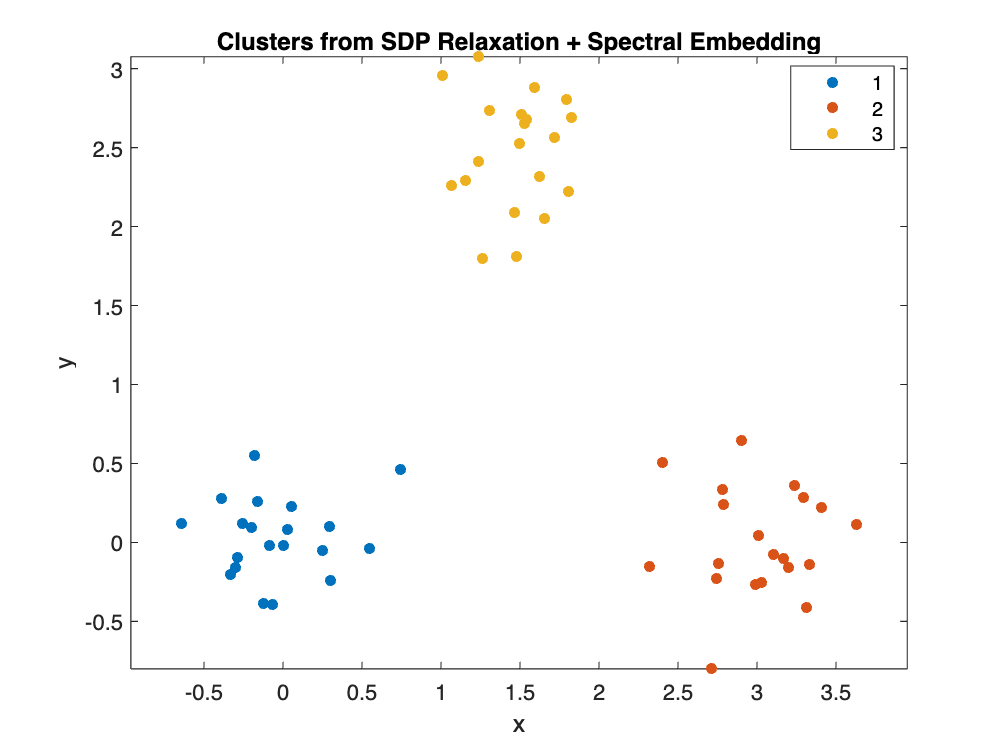


% Post-processing: Extract clusters from SDP output
% (Top-k eigenvectors + k-means as per standard SDP post-processing)
[V, ~] = eigs(X_sdp, k);
cluster_labels = kmeans(V, k);

% Plot clustering result
figure;
gscatter(P(1, :), P(2, :), cluster_labels);
title('Clusters from SDP Relaxation + Spectral Embedding');
xlabel('x'); ylabel('y');
axis equal;